% gpuDeviceCount("available")
% gpuDeviceTable

out

out =   Simulink.SimulationOutput:

           bicycle_yaw_rad: [1x1 timeseries] 
     bicycle_ydot_body_rad: [1x1 timeseries] 
                 input_acc: [1x1 timeseries] 
            input_turn_rad: [1x1 timeseries] 
                   logsout: [1x1 Simulink.SimulationData.Dataset] 
                plant_pose: [1x1 struct] 
                 scen_pose: [1x1 struct] 
                solverStat: [1x1 timeseries] 
                      tout: [3001x1 double] 

        SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
              ErrorMessage: [0x0 char] 


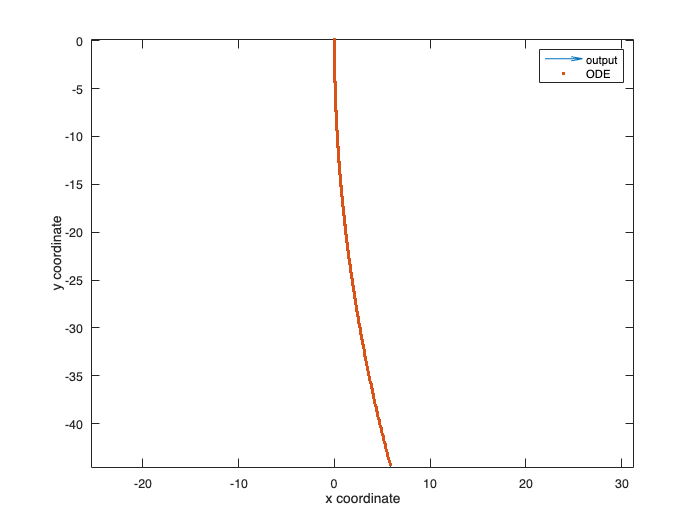

% simulation trajectory
time_out_plant_position=out.plant_pose.Position.Time;
out_plant_position=out.plant_pose.Position.Data;
out_plant_position=reshape(out_plant_position,[3, size(out_plant_position,3)]);
out_plant_velocity=out.plant_pose.Velocity.Data;
out_plant_velocity=reshape(out_plant_velocity,[3, size(out_plant_velocity,3)]);

figure
quiver(out_plant_position(1,:), out_plant_position(2,:), ...
    out_plant_velocity(1,:), out_plant_velocity(2,:),0.1)
hold on 
axis equal
xlabel('x coordinate')
ylabel('y coordinate')

% ODE trajectory
ODE_model=bicycleKinematics("WheelBase",3,'VehicleInputs','VehicleSpeedSteeringAngle');
ODE_initState=[0 0.12 -pi/2];% x, y, yaw[rad]
ODE_Pos=[ODE_initState];
ODE_Tspan=T0:0.1:30;

ODE_v=[0:0.01:3];
ODE_steer=ones(1,301).*deg2rad(1);
ODE_inputs = [ODE_v' ODE_steer'];

for i=1:300
    ODE_input=ODE_inputs(i,:);

    [t,ODE_pos] = ode45(@(t,ODE_pos)derivative(ODE_model, ODE_pos, ODE_input), ...
      [ODE_Tspan(i), ODE_Tspan(i+1)], ODE_initState);

    ODE_initState=ODE_pos(end,:);
    ODE_Pos=[ODE_Pos;ODE_initState];
end

% quiver(ODE_x_traj, ODE_y_traj, ...
%     ODE_vx_traj, ODE_vy_traj,0.1)
plot(ODE_Pos(:,1),ODE_Pos(:,2),'.');

legend('output','ODE')

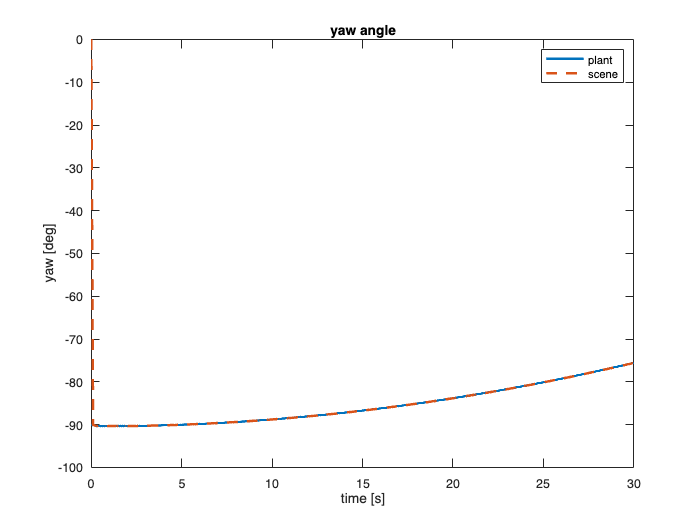






time_out_bicycle_yaw_rad=out.bicycle_yaw_rad.Time;
out_bicycle_yaw_rad=out.bicycle_yaw_rad.Data;
out_bicycle_yaw=rad2deg(out_bicycle_yaw_rad);
% out_bicycle_yaw=reshape(out_bicycle_yaw,[size(out_bicycle_yaw,3),1])

figure
plot(time_out_bicycle_yaw,out_bicycle_yaw,LineWidth=2)
hold on
xlabel('time [s]')
ylabel('yaw [deg]')
title('yaw angle')

time_out_scen_yaw=out.scen_pose.Yaw.Time;
out_scen_yaw=out.scen_pose.Yaw.Data;
out_scen_yaw=reshape(out_scen_yaw,[size(out_scen_yaw,3),1]);

plot(time_out_scen_yaw, out_scen_yaw,'--',LineWidth=2)
legend('plant','scene')


out_input_acc=out.input_acc.Data

out_input_acc =    200
   200
   200
   200
   200
   200
   200
   200
   200
   200


out_input_turn_rad=out.input_turn_rad.Data;
out_input_turn=rad2deg(out_input_turn_rad)

out_input_turn =     0.3600
    0.7200
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



out_bicycle_ydot_body_rad=out.bicycle_ydot_body_rad.Data;
bicycle_ydot_body=rad2deg(out_bicycle_ydot_body_rad)

bicycle_ydot_body =          0
    0.0187
   -1.7399
   -1.6082
   -1.4263
    1.2767
    0.6745
   -3.0729
   -1.4954
   -0.5600


function [x_traj, y_traj, vx_traj, vy_traj, yaw_traj] = ODE_sim(T, x0, y0, yaw0, acc, steer)
    x_traj=x0;
    y_traj=y0;
    vx_traj=0;
    vy_traj=0;
    yaw_traj=yaw0;

    dt=T(2)-T(1);
    v=0;
    yaw=yaw0;
    for t=T
        [dx, dy, dyaw, dv] = ODE_dynamics(dt, v, yaw, acc, steer);
        
        x_traj=[x_traj x_traj(end)+dx];
        y_traj=[y_traj y_traj(end)+dy];

        vx_traj=[vx_traj v*cosd(yaw)];
        vy_traj=[vy_traj v*sind(yaw)];

        yaw=yaw+dyaw;
        v=v+dv;

        yaw_traj=[yaw_traj yaw];

    end
end
function [dx, dy, dyaw, dv] = ODE_dynamics(dt, v, yaw, acc, steer)
    % Vehicle dynamics equations - continuous
    L=3;

    dx = v*cosd(yaw)*dt;
    dy = v*sind(yaw)*dt;
    dyaw = v*tand(steer)/L*dt;
    dv = acc*dt;
end